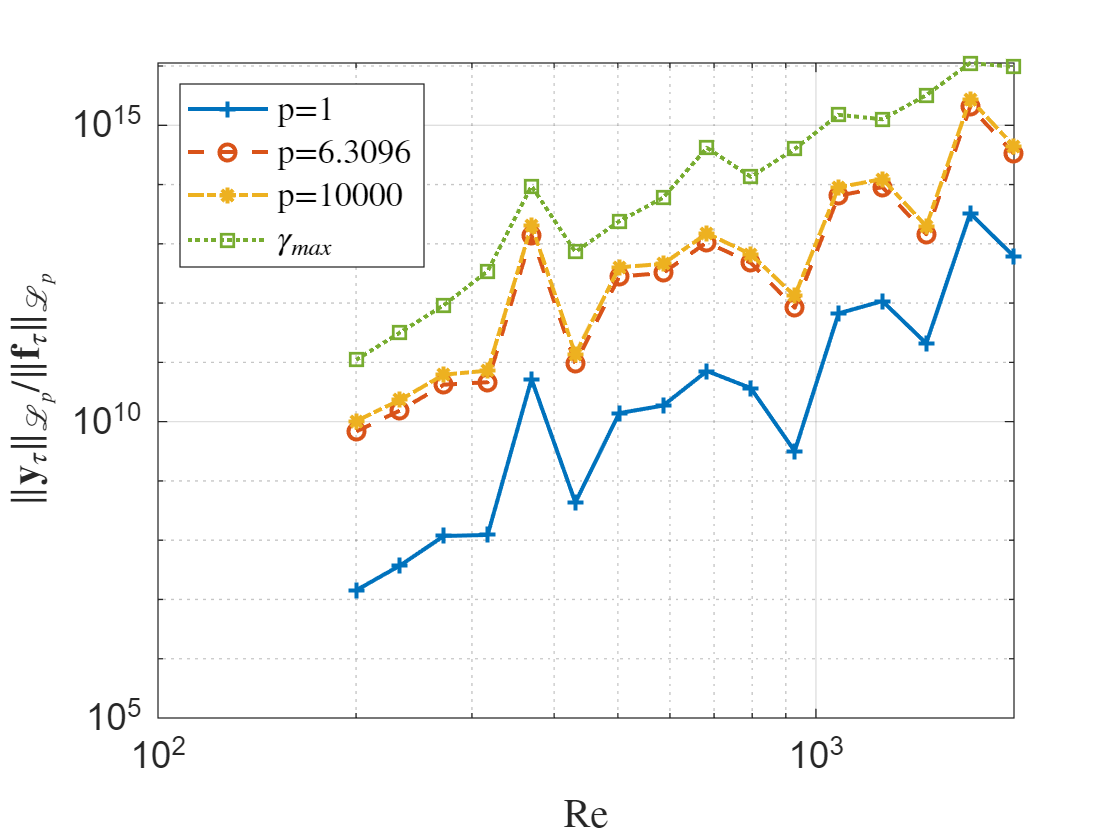

colors = lines(16);
line_styles = {"-","--","-.",":",""};
markers = {'+', 'o', '*', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
line_width = 1.5;
figure;
% Plot each line with a unique label for the legend
h1 = loglog(Re_list, prop_y_u(:,1), ...
'LineStyle', line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :), 'Marker', markers{1});
hold on;
h2 = loglog(Re_list, prop_y_u(:,4),...
'LineStyle', line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :), 'Marker', markers{2});
h3 = loglog(Re_list, prop_y_u(:,16),...
'LineStyle', line_styles{3}, 'LineWidth', line_width, 'Color', colors(3, :), 'Marker', markers{3});
% h4 = loglog(Re_list, prop_y_u(:,16), ...
% 'LineStyle', line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :), 'Marker', markers{4});
h4 = loglog(Re_list, Gamma_theorem_max(:,:), ...
'LineStyle', line_styles{4}, 'LineWidth', line_width, 'Color', colors(5, :), 'Marker', markers{5});
hold off;
xlim([1e2, 2000]);  
xlabel('Re', 'FontSize', 12, 'Interpreter', 'latex');
ylabel('$\|\mathbf{y}_\tau\|_{\mathcal{L}_p}/\|\mathbf{f}_\tau\|_{\mathcal{L}_p}$', 'FontSize', 12,'Interpreter', 'latex');
legend([h1, h2, h3, h4], {'p=1','p=6.3096','p=10000','$\gamma_{max}$'}, 'Location', 'northwest','Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 14);
hold off;